# UR5e Control for RoboCup ARM Challenge

## Setup the Virtual Simulation Environment

[**Instructions to setup RoboCup ARM provided virtual machine**](https://drive.google.com/file/d/1w9tBy3DKmZBKEfOqOFUXcT8hcQig6sNS/view)** (Appendix A)**

Follow the instructions above to setup the MathWorks provided Virtual Machine in your computer.

Find and open one of the environments for the RoboCup ARM Challenge. Note that there is more than on environment provided to ilustrate how objects in the environments are subject to changing positions and orientations based on the challenge instructions. 

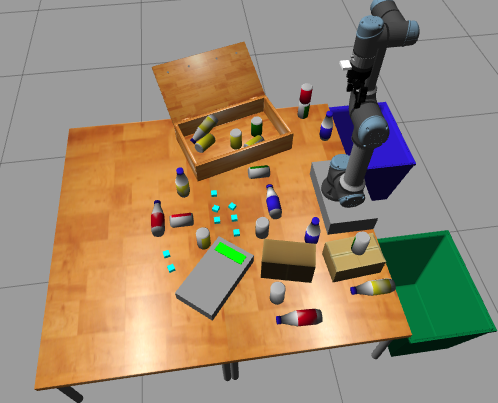

#### Connect MATLAB to Gazebo using the ROS Toolbox

Start a ROS node from MATLAB to interact with the Gazebo environment. For more information on interaction with the ROS ecosystem from MATLAB visit [Getting Started with ROS Toolbox](https://www.mathworks.com/help/ros/getting-started-with-ros-toolbox.html).

If you are having trouble with this step, or if you are waiting a long time for the nodes to communicate, try using the commented code in line 4. The IP address to be specified is the wireless network adapter address.

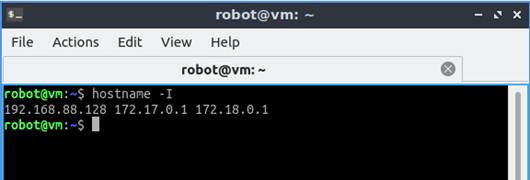

rosIP = "192.168.8.46"; % Change IP address!!    % IP address of ROS enabled machine  
rosshutdown; % shut down existing connection to ROS

Shutting down global node /matlab_global_node_59386 with NodeURI http://192.168.8.46:45221/ and MasterURI http://192.168.8.46:11311.


rosinit(rosIP,11311);

Initializing global node /matlab_global_node_16468 with NodeURI http://192.168.8.46:42967/ and MasterURI http://192.168.8.46:11311.


% rosinit(rosIP,'NodeHost','172.31.201.75') % Try specifying node host IP in case that there are multiple network adapters
% rosinit(rosIP,11311,'NodeHost','192.168.68.123');


rostopic list

/camera/depth/camera_info                                  
/camera/depth/image_raw                                    
/camera/depth/points                                       
/camera/parameter_descriptions                             
/camera/parameter_updates                                  
/camera/rgb/camera_info                                    
/camera/rgb/image_raw                                      
/clock                                                     
/ft_sensor/raw                                             
/gazebo/link_states                                        
/gazebo/model_states                                       
/gazebo/parameter_descriptions                             
/gazebo/parameter_updates                                  
/gazebo/performance_metrics                                
/gazebo/set_link_state                                     
/gazebo/set_model_state                                    
/grasp_event_republisher/grasp_events   

## Control Gripper Using ROS Action Client

Initialize ROS action client.

[gripAct,gripGoal] = rosactionclient('/gripper_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory')

gripAct =   SimpleActionClient with properties:

           ActionName: '/gripper_controller/follow_joint_trajectory'
           ActionType: 'control_msgs/FollowJointTrajectory'
    IsServerConnected: 0
                 Goal: [1×1 FollowJointTrajectoryGoal]
            GoalState: ''
        ActivationFcn: @(~)disp('Goal active')
          FeedbackFcn: @(~,msg)disp(['Feedback: ',showDetailsAnyFormat(msg)])
            ResultFcn: @(~,res)disp(['Final state ',res.State,' with result: ',showDetailsAnyFormat(res.Message)])
           DataFormat: 'object'


gripGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [0×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


gripAct.FeedbackFcn = [];

Pack ROS message and send goal to gripper controller.

gripPos = 0.8; %0 is fully open, 0.8 is fully closed
gripGoal=packGripGoal(gripPos,gripGoal)

gripGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [1×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


sendGoal(gripAct,gripGoal);

## Control Gripper Position using ROS Action Client

### Initialize ROS Action Client

[trajAct,trajGoal] = rosactionclient('/pos_joint_traj_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory') 

trajAct =   SimpleActionClient with properties:

           ActionName: '/pos_joint_traj_controller/follow_joint_trajectory'
           ActionType: 'control_msgs/FollowJointTrajectory'
    IsServerConnected: 0
                 Goal: [1×1 FollowJointTrajectoryGoal]
            GoalState: ''
        ActivationFcn: @(~)disp('Goal active')
          FeedbackFcn: @(~,msg)disp(['Feedback: ',showDetailsAnyFormat(msg)])
            ResultFcn: @(~,res)disp(['Final state ',res.State,' with result: ',showDetailsAnyFormat(res.Message)])
           DataFormat: 'object'


trajGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [0×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


trajAct.FeedbackFcn = []; 
jointSub = rossubscriber("/joint_states")

jointSub =   Subscriber with properties:

                      TopicName: '/joint_states'
                  LatestMessage: [0×1 JointState]
                    MessageType: 'sensor_msgs/JointState'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: []
                     DataFormat: 'object'


jointStateMsg = jointSub.LatestMessage

jointStateMsg =   0×1 ROS JointState message array with properties:

    MessageType
    Header
    Name
    Position
    Velocity
    Effort


### Setup Robot Model for Inverse Kinematics

The ROS Action that controls the robot uses the position of the individual joints as an input. In roder to make it easier to establish a cartesian target location it is necessary to have a robot model for which to [calculate the inverse kinmetics.](https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html)

UR5e = loadrobot('universalUR5e')

UR5e =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


RobotConfiguration = homeConfiguration(UR5e);
%Method compensation

% Adjust body transformations from previous URDF version
tform=UR5e.Bodies{3}.Joint.JointToParentTransform;
UR5e.Bodies{3}.Joint.setFixedTransform(tform*eul2tform([pi/2,0,0]));
tform=UR5e.Bodies{4}.Joint.JointToParentTransform;
UR5e.Bodies{4}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));
tform=UR5e.Bodies{7}.Joint.JointToParentTransform;
UR5e.Bodies{7}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));

% ik = inverseKinematics("RigidBodyTree",UR5e); % Create Inverse kinematics solver

% ikWeights = [0.25 0.25 0.25 0.1 0.1 .1]; % configuration weights for IK solver [Translation Orientation] see documentationT06
jointStateMsg = receive(jointSub,3) % receive current robot configuration

jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


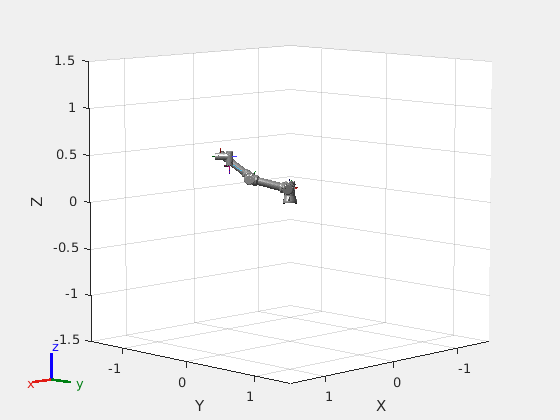

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



RobotConfiguration(1).JointPosition = jointStateMsg.Position(4); % update configuration in initial guess
RobotConfiguration(2).JointPosition = jointStateMsg.Position(3);
RobotConfiguration(3).JointPosition = jointStateMsg.Position(1);
RobotConfiguration(4).JointPosition = jointStateMsg.Position(5);
RobotConfiguration(5).JointPosition = jointStateMsg.Position(6);
RobotConfiguration(6).JointPosition = jointStateMsg.Position(7);

show(UR5e,RobotConfiguration)

%%%

## Move the system to the initial configuration

RobotConfiguration(1).JointPosition = 0; % update configuration in initial guess
RobotConfiguration(2).JointPosition = 0;
RobotConfiguration(3).JointPosition = 0;
RobotConfiguration(4).JointPosition = 0;
RobotConfiguration(5).JointPosition = 0;
RobotConfiguration(6).JointPosition = 0;

UR5econfig = [RobotConfiguration(3).JointPosition RobotConfiguration(2).JointPosition...
    RobotConfiguration(1).JointPosition RobotConfiguration(4).JointPosition...
    RobotConfiguration(5).JointPosition RobotConfiguration(6).JointPosition];
trajGoal = packTrajGoal(UR5econfig,trajGoal)

trajGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [6×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


sendGoal(trajAct,trajGoal);

### Set End-Effector Pose

This section has interactive controls to set the cartesian position of the robot end-effector and use the inverse kinematics solver to calculate teh necessary robot configuration.

gripperX = 0;
gripperY = 0.5;
gripperZ = 0.3;

gripperTranslation = [gripperX gripperY gripperZ];
gripperRotation = [pi -pi 0]; %  [Z Y X]radians


tform = eul2tform(gripperRotation); %
tform(1:3,4) = gripperTranslation' % set translation in homogeneous transform

tform =     1.0000   -0.0000    0.0000         0
   -0.0000   -1.0000   -0.0000    0.5000
    0.0000         0   -1.0000    0.3000
         0         0         0    1.0000



% [configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess) %Used
% in previos, not Campus Tampico, version.

pesoMotores = [0.5 0.7 0.9 0.3 0.2 0.1]';
RobotConfiguration = InverseKinematicUR5eITESMTampico(tform,RobotConfiguration,pesoMotores)

ans = "Se ha encontrado una salida, se ha seleccionado y ajustado sumando la constante de simulación"

RobotConfiguration = 1×6 struct array with fields:
    JointName
    JointPosition


% show(UR5e,RobotConfiguration)

### Send Joint Trajectory Goal 

Packing the robot configuration into the appropriate ROS Action goal message and sending it to the robot controller.

UR5econfig = [RobotConfiguration(3).JointPosition RobotConfiguration(2).JointPosition...
    RobotConfiguration(1).JointPosition RobotConfiguration(4).JointPosition...
    RobotConfiguration(5).JointPosition RobotConfiguration(6).JointPosition];
trajGoal = packTrajGoal(UR5econfig,trajGoal)

trajGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [6×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


sendGoal(trajAct,trajGoal);


jointStateMsg = receive(jointSub,3) 

jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message



RobotConfiguration = InverseKinematicUR5eITESMTampico(BoteVerde(),RobotConfiguration,pesoMotores)

tform =     1.0000   -0.0000    0.0000    0.5000
   -0.0000   -1.0000   -0.0000   -0.4000
    0.0000         0   -1.0000    0.4000
         0         0         0    1.0000


ans = "Se ha encontrado una salida, se ha seleccionado y ajustado sumando la constante de simulación"

RobotConfiguration = 1×6 struct array with fields:
    JointName
    JointPosition



UR5econfig = [RobotConfiguration(3).JointPosition RobotConfiguration(2).JointPosition...
    RobotConfiguration(1).JointPosition RobotConfiguration(4).JointPosition...
    RobotConfiguration(5).JointPosition RobotConfiguration(6).JointPosition];
trajGoal = packTrajGoal(UR5econfig,trajGoal)

trajGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [6×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


sendGoal(trajAct,trajGoal);

q = zeros(6,1);

while true
    jointStateMsg = receive(jointSub,3)
    q(1) = RobotConfiguration(1).JointPosition - jointStateMsg.Position(4);
    q(1) = RobotConfiguration(2).JointPosition - jointStateMsg.Position(3);
    q(1) = RobotConfiguration(3).JointPosition - jointStateMsg.Position(1);
    q(1) = RobotConfiguration(4).JointPosition - jointStateMsg.Position(5);
    q(1) = RobotConfiguration(5).JointPosition - jointStateMsg.Position(6);
    q(1) = RobotConfiguration(6).JointPosition - jointStateMsg.Position(7);
    if norm(q) < 0.05
        break
    end
end

jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message



gripPos = 0.0; %0 is fully open, 0.8 is fully closed
gripGoal=packGripGoal(gripPos,gripGoal)

gripGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [1×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


sendGoal(gripAct,gripGoal);
gripSet = 0;

while true
    jointStateMsg = receive(jointSub,3)
    if abs(jointStateMsg.Position(2)) < 0.1
        break
    end
end

jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message




RobotConfiguration = InverseKinematicUR5eITESMTampico(BoteAzul(),RobotConfiguration,pesoMotores)

tform =     1.0000   -0.0000    0.0000   -0.5000
   -0.0000   -1.0000   -0.0000   -0.4000
    0.0000         0   -1.0000    0.4000
         0         0         0    1.0000


ans = "Se ha encontrado una salida, se ha seleccionado y ajustado sumando la constante de simulación"

RobotConfiguration = 1×6 struct array with fields:
    JointName
    JointPosition



UR5econfig = [RobotConfiguration(3).JointPosition RobotConfiguration(2).JointPosition...
    RobotConfiguration(1).JointPosition RobotConfiguration(4).JointPosition...
    RobotConfiguration(5).JointPosition RobotConfiguration(6).JointPosition];
trajGoal = packTrajGoal(UR5econfig,trajGoal)

trajGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [6×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


sendGoal(trajAct,trajGoal);

function tform = BoteVerde()
    gripperTranslation = [0.5,-0.4,0.4];
    gripperRotation = [pi -pi 0]; %  [Z Y X]radians

    tform = eul2tform(gripperRotation); %
    tform(1:3,4) = gripperTranslation' % set translation in homogeneous transform
end


function tform = BoteAzul()
    gripperTranslation = [-0.5,-0.4,0.4];
    gripperRotation = [pi -pi 0]; %  [Z Y X]radians

    tform = eul2tform(gripperRotation); %
    tform(1:3,4) = gripperTranslation' % set translation in homogeneous transform
end


tform =    -0.0000    1.0000   -0.0000   -0.0100
    1.0000    0.0000    0.0000    0.4900
    0.0000         0   -1.0000    0.9300
         0         0         0    1.0000


% UR5econfig = [0 pi/2 0 0 0 pi/2];
% trajGoal = packTrajGoal(UR5econfig,trajGoal)
% sendGoal(trajAct,trajGoal);

## Receive Camera Image Using ROS Subscriber

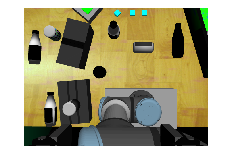

rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
pause(1)
curImage = receive(rgbImgSub,3);
rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
imshow(rgbImg)

## Receive Depth Image Using ROS Subscriber

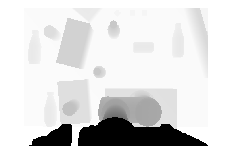

rgbDptSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
curDepth = receive(rgbDptSub,3);
depthImg = rosReadImage(rgbDptSub.LatestMessage); 
imshow(depthImg)

### Appendix - Utilities

This section contains two functions that can be reused for packing the goal information for the ROS action goals to the appropriate message structures.

function gripGoal=packGripGoal(pos,gripGoal)
    jointWaypointTimes = 3;
    jointWaypoints = [pos]';
    numJoints = size(jointWaypoints,1);
    gripGoal.Trajectory.JointNames = {'robotiq_85_left_knuckle_joint'};
    gripGoal.GoalTolerance = rosmessage('control_msgs/JointTolerance');
    gripGoal.GoalTolerance.Name = gripGoal.Trajectory.JointNames{1};
    gripGoal.GoalTolerance.Position = 0;
    gripGoal.GoalTolerance.Velocity = 0.1;
    gripGoal.GoalTolerance.Acceleration = 0.1;
    
    trajPts = rosmessage('trajectory_msgs/JointTrajectoryPoint');
    trajPts.TimeFromStart = rosduration(jointWaypointTimes);
    trajPts.Positions = jointWaypoints;
    trajPts.Velocities = zeros(size(jointWaypoints));
    trajPts.Accelerations = zeros(size(jointWaypoints));
    trajPts.Effort = zeros(size(jointWaypoints));
    
    gripGoal.Trajectory.Points = trajPts;
end

function trajGoal = packTrajGoal(config,trajGoal)
    jointWaypointTimes = 3;
    jointWaypoints = config';
    numJoints = size(jointWaypoints,1);
    
    trajGoal.Trajectory.JointNames = {'elbow_joint','shoulder_lift_joint','shoulder_pan_joint','wrist_1_joint','wrist_2_joint','wrist_3_joint'};
    
    for idx = 1:numJoints
    
        trajGoal.GoalTolerance(idx) = rosmessage('control_msgs/JointTolerance');
        trajGoal.GoalTolerance(idx).Name = trajGoal.Trajectory.JointNames{idx};
        trajGoal.GoalTolerance(idx).Position = 0;
        trajGoal.GoalTolerance(idx).Velocity = 0;
        trajGoal.GoalTolerance(idx).Acceleration = 0;
    
    end
    
    trajPts = rosmessage('trajectory_msgs/JointTrajectoryPoint');
    trajPts.TimeFromStart = rosduration(jointWaypointTimes);
    trajPts.Positions = jointWaypoints;
    trajPts.Velocities = zeros(size(jointWaypoints));
    trajPts.Accelerations = zeros(size(jointWaypoints));
    trajPts.Effort = zeros(size(jointWaypoints));
    
    trajGoal.Trajectory.Points = trajPts;
end

function RobotConfiguration = InverseKinematicUR5eITESMTampico(tform,RobotConfiguration,pesoMotores)
    %Unidades en m

    k = [pi/2 pi/2 0 0 +pi/2 0]';

    escala = 1;
    d_1 = 0.1625*escala;
    d_4 = 0.1333*escala;
    d_5 = 0.0997*escala;
    d_6 = 0.0996*escala;

    a_2 = -0.425*escala;
    a_3 = -0.3922*escala;

    numSol = 16;
    theta = zeros(6,numSol);
    p05x= tform(1,4)-d_6*tform(1,3);
    p05y= tform(2,4)-d_6*tform(2,3);
    theta(1,1:numSol/2)= atan2(p05y,p05x)+acos(d_4/(sqrt(p05x^2+p05y^2)))+pi/2;
    theta(1,numSol/2+1:end)= atan2(p05y,p05x)-acos(d_4/(sqrt(p05x^2+p05y^2)))+pi/2;

    for i = 1:16
        try
            if mod(i,8)==1
                p16z= tform(1,4)*sin(theta(1,i))-tform(2,4)*cos(theta(1,i));
                theta(5,i:i+3) = acos((p16z-d_4)/d_6);
                theta(5,i+4:i+7) = -theta(5,i);
            end
            if mod(i,4)==1
                T01 = mi_HT(theta(1,i),d_1,0,pi/2);
                T45 = mi_HT(theta(5,i),d_5,0,-pi/2);
                zy=tform(1,2)*sin(theta(1,i))-tform(2,2)*cos(theta(1,i));
                zx=tform(1,1)*sin(theta(1,i))-tform(2,1)*cos(theta(1,i));
                theta(6,i:i+3)= atan2(-zy/sin(theta(5,i)),zx/sin(theta(5,i)));
                T56 = mi_HT(theta(6,i),d_6,0,0);
                T14 = (T01\tform)/(T45*T56);
                p13 =T14*[0; -d_4; 0; 1] - [0; 0; 0; 1];
                p13m=norm(p13);
                theta(3,[i i+1])=-acos((p13m^2-a_2^2-a_3^2)/(2*a_2*a_3));
                theta(3,[i+2 i+3])=acos((p13m^2-a_2^2-a_3^2)/(2*a_2*a_3));
            end
            if mod(i,2)==1
                T23 = mi_HT(theta(3,i),0,a_3,0);
                theta(2,i) = -atan2(p13(2),-p13(1))+asin(a_3*sin(theta(3,i))/p13m);
                theta(2,i+1) = -atan2(p13(2),-p13(1))-asin(a_3*sin(theta(3,i))/p13m);
            end

            T12 = mi_HT(theta(2,i),0,a_2,0);
            T34=(T12*T23)\T14;
            theta(4,i) = atan2(T34(2,1),T34(1,1));
        catch
            theta(:,i)=NaN;
        end
    end
    q_Anterior = [RobotConfiguration(1).JointPosition,RobotConfiguration(2).JointPosition,...
                  RobotConfiguration(3).JointPosition,RobotConfiguration(4).JointPosition,...
                  RobotConfiguration(5).JointPosition,RobotConfiguration(6).JointPosition]';

    for i=1:numSol
        temp0 = mi_HT(theta(1,i),d_1,0,pi/2)*mi_HT(theta(2,i),0,a_2,0)*...
        mi_HT(theta(3,i),0,a_3,0)*mi_HT(theta(4,i),d_4,0,pi/2)*...
        mi_HT(theta(5,i),d_5,0,-pi/2)*mi_HT(theta(6,i),d_6,0,0);
        P(:,i) = temp0(1:3,4);
    end

    temp1 = sum((P-tform(1:3,4)).^2,1);
    theta = theta(:,temp1 < 0.001);
    temp2 = pesoMotores'*(theta-q_Anterior).^2;
    q = theta(:,temp2 == min(temp2));

    if isempty(q)
        sprintf("Salida vacia, se ha seleccionado de forma arbitraria")
        RobotConfiguration(1).JointPosition=0;
        RobotConfiguration(2).JointPosition=0; 
        RobotConfiguration(3).JointPosition=0; 
        RobotConfiguration(4).JointPosition=0; 
        RobotConfiguration(5).JointPosition=0; 
        RobotConfiguration(6).JointPosition=0; 
    else
        sprintf("Se ha encontrado una salida, se ha seleccionado y ajustado sumando la constante de simulación")
        RobotConfiguration(1).JointPosition=q(1)+k(1);
        RobotConfiguration(2).JointPosition=q(2)+k(2); 
        RobotConfiguration(3).JointPosition=q(3)+k(3); 
        RobotConfiguration(4).JointPosition=q(4)+k(4); 
        RobotConfiguration(5).JointPosition=q(5)+k(5); 
        RobotConfiguration(6).JointPosition=q(6)+k(6); 
    end

end

function output = mi_HT(theta,d,a,alpha)
    output = [cos(theta) -sin(theta) 0 0;
              sin(theta) cos(theta) 0 0;
              0 0 1 0;
              0 0 0 1]*...
              [eye(3),[a;0;d];[0 0 0 1]]*...
              [1 0 0 0;
              0 cos(alpha) -sin(alpha) 0;
              0 sin(alpha) cos(alpha) 0;
              0 0 0 1]; 
end